## Assignment #1

### 1) Time response simulation

The plant is G(s) = 1 / ((s+1)^3)

Simulate it with Kp = 1, 2 and 5

%defining plant
num1 = [1];
den1 = [1 3 3 1];
G1 = tf(num1,den1)

G1 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.




%alternatively
s = tf('s');
G2 = 1 / (s^3 + 3*s^2 + 3*s + 1)

G2 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



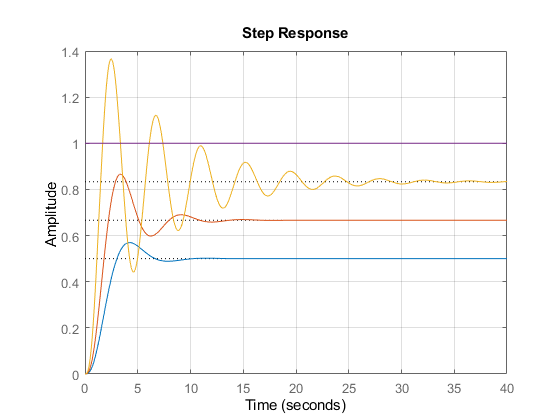


% full model tf including controller and feedbacks
Kp1 = 1; Kp2 = 2; Kp3 = 5;
sys1 = feedback(G1*Kp1, 1);
sys2 = feedback(G1*Kp2, 1);
sys3 = feedback(G1*Kp3, 1);

% plotting step responses
figure; step(sys1, sys2, sys3,tf(1,1) ); grid;

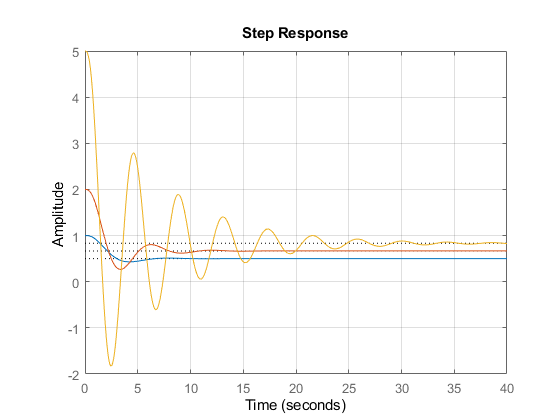


% control signal ( formula is U/X = C / 1+GC ) 
sys4 = feedback(Kp1, G1, -1);
sys5 = feedback(Kp2, G1, -1);
sys6 = feedback(Kp3, G1, -1);
figure; step(sys4, sys5, sys6);grid;

### 2) Frequency response simulation

The plant is G(s) = 1 / (s+10)

Find freq response

Find freq response with PID (Kp' = 6, Ti' = 4, Td' = 1)

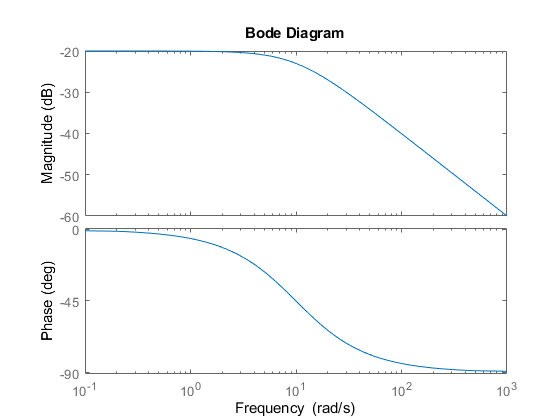

% this part includes two PID models (interacting and non-interacting)
Kpd = 6; Tid = 4; Tdd = 1;
Kp = Kpd*(Tid+Tdd)/Tid;
Ti = Tid+Tdd;
Td = Tid*Tdd/(Tid+Tdd);

% freq response of the plant
sys = tf(1, [1 10]);
bode(sys)


% interacting PID block
PID = Kpd*(1+1/(s*Tid)+s*Tdd)

PID =
 
  24 s^2 + 24 s + 6
  -----------------
         4 s
 
Continuous-time transfer function.



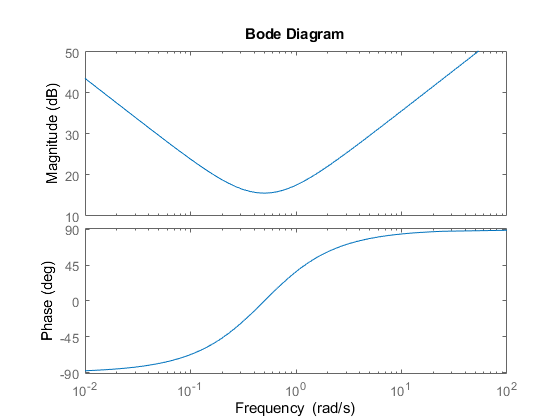

bode(PID)

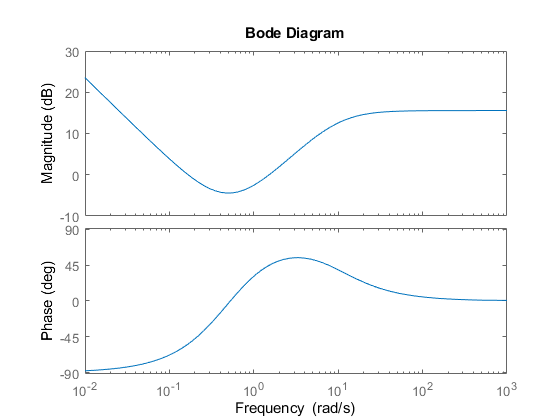

% bode of controlled system
bode(sys*PID)


% non-interacting PID block
nPID = Kp*(1+1/(s*Ti)+s*Td)

nPID =
 
  30 s^2 + 37.5 s + 7.5
  ---------------------
           5 s
 
Continuous-time transfer function.



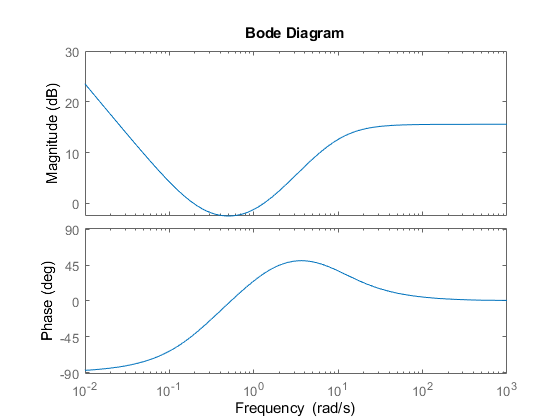

% bode of controlled system
bode(sys*nPID)